## Preliminaries

load('Simulation_Results_V1.mat');

% period_of_interest = 1.5:0.0005:1.9;
% indices_of_interest = round(period_of_interest/0.0005) + 1;

% i_time = 1;
% i_E_net = 2;
% i_E_pos = 3;
% i_E_neg = 4;
% i_F = 5;
% i_v_m = 6;
% i_v_t = 7;
% i_v_MTU = 8;
% i_P_m = 9;
% i_P_t = 10;
% i_P_MTU = 11;

## Plotting Fatigue

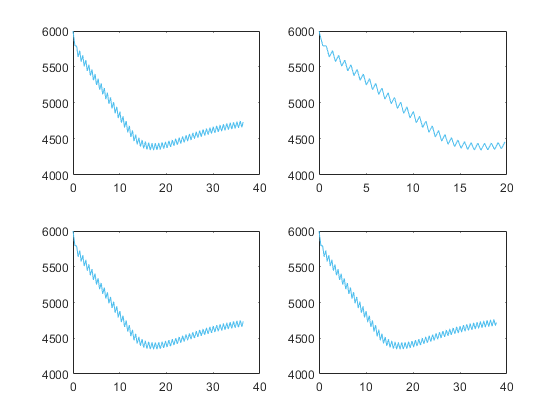

phase_range = 0.4.*(-0.5:0.025:0.5) + 0.3;
phase_percents = -50:2.5:50;
stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];

stiffness = 1.8E5;
count = 1;

for k = 1:length(All_Data_Cell_Array_Matrix)
    for p = 1:length(All_Data_Cell_Array_Matrix{1})
        current_iteration_time_series_array = All_Data_Cell_Array_Matrix{1, k}{1, p};
        F_current_exertable = current_iteration_time_series_array.Data(:,8);
        time_vec = current_iteration_time_series_array.Time;
        subplot(2,2,count)
        plot(time_vec, F_current_exertable);
        count = count + 1;
        hold on
    end 
    hold on
end
hold on

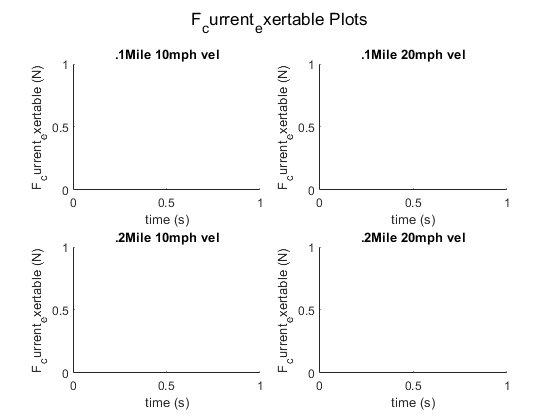


figure(1)
figure("Name", "F_current_exertable Plots");
hold on;
ax_1 = subplot(2, 2, 1);
title('.1Mile 10mph vel');
ylabel('F_current_exertable (N)');
xlabel('time (s)');

ax_2 = subplot(2, 2, 2);

title('.1Mile 20mph vel');
ylabel('F_current_exertable (N)');
xlabel('time (s)');

ax_3 = subplot(2, 2, 3);
title('.2Mile 10mph vel');
ylabel('F_current_exertable (N)');
xlabel('time (s)');

ax_3 = subplot(2, 2, 4);
title('.2Mile 20mph vel');
ylabel('F_current_exertable (N)');
xlabel('time (s)');
%linkaxes([ax_1,ax_2,ax_3],'y');

sgtitle("F_current_exertable Plots");
hold off;






% 

## 3b: Muscle versus Tendon F, V, & P

phase_range = 0.4.*[0, 0.275, 0.375] + 0.3;
phase_percents = [0, 0.275, 0.375];
stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];

stiffness = 1.8E5;
for phi = 1:length(phase_range)
    phase = phase_range(phi);
    load(strcat('data/p=',num2str(phase),'_k=',num2str(stiffness),'.mat'));
    if phi == 1
        data_fvp = zeros(length(phase_range), 7, length(out));
    end
    data_fvp(phi, :, :) = out(5:11,:);
end

Error using load
Unable to read file 'data/p=0.3_k=180000.mat'. No such file or directory.


time = out(1, :);

figure("Name", "3b");
hold on;

ax_01 = subplot(3, 3, 1);
plot(period_of_interest, reshape(data_fvp(1, 1, indices_of_interest), [1 801]), "Color", "black");
ylabel('Force (N)');
title("0%");

ax_02 = subplot(3, 3, 2);
plot(period_of_interest, reshape(data_fvp(2, 1, indices_of_interest), [1 801]), "Color", "black");
title("27.5%");

ax_03 = subplot(3, 3, 3);
plot(period_of_interest, reshape(data_fvp(3, 1, indices_of_interest), [1 801]), "Color", "black");
title("37.5%");

ax_04 = subplot(3, 3, 4);
hold on;
plot(period_of_interest, -1* reshape(data_fvp(1, 2, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, -1* reshape(data_fvp(1, 3, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, -1* reshape(data_fvp(1, 4, indices_of_interest), [1 801]), "Color", "green");
ylabel('Velocity (m/s)');
hold off;

ax_05 = subplot(3, 3, 5);
hold on;
plot(period_of_interest, -1* reshape(data_fvp(2, 2, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, -1* reshape(data_fvp(2, 3, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, -1* reshape(data_fvp(2, 4, indices_of_interest), [1 801]), "Color", "green");
hold off;

ax_06 = subplot(3, 3, 6);
hold on;
plot(period_of_interest, -1* reshape(data_fvp(3, 2, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, -1* reshape(data_fvp(3, 3, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, -1* reshape(data_fvp(3, 4, indices_of_interest), [1 801]), "Color", "green");
hold off;

ax_07 = subplot(3, 3, 7);
hold on;
plot(period_of_interest, reshape(data_fvp(1, 5, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, reshape(data_fvp(1, 6, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, reshape(data_fvp(1, 7, indices_of_interest), [1 801]), "Color", "green");
ylabel('Power (W)');
hold off;

ax_08 = subplot(3, 3, 8);
hold on;
plot(period_of_interest, reshape(data_fvp(2, 5, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, reshape(data_fvp(2, 6, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, reshape(data_fvp(2, 7, indices_of_interest), [1 801]), "Color", "green");
xlabel('Time (s)');
legend(["CE", "SEE", "MTU"], "Location", "south", "NumColumns", 3);
hold off;

ax_09 = subplot(3, 3, 9);
hold on;
plot(period_of_interest, reshape(data_fvp(3, 5, indices_of_interest), [1 801]), "Color", "red");
plot(period_of_interest, reshape(data_fvp(3, 6, indices_of_interest), [1 801]), "Color", "blue");
plot(period_of_interest, reshape(data_fvp(3, 7, indices_of_interest), [1 801]), "Color", "green");
hold off;

sgtitle('MTU Component Kinematics at different Phase Delays') 

linkaxes([ax_01,ax_02,ax_03],'y');
linkaxes([ax_04,ax_05,ax_06],'y');
linkaxes([ax_07,ax_08,ax_09],'y');

## 3c: MTU Work by Stiffness

phase_range = 0.4.*(-0.5:0.025:0.5) + 0.3;
phase_percents = -50:2.5:50;
stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];

for phi = 1:length(phase_range)
    for k = 1:length(stiffness_range)
        phase = phase_range(phi);
        stiffness = stiffness_range(k);
        load(strcat('data/p=',num2str(phase),'_k=',num2str(stiffness),'.mat'));
        
        if (phi == 1 && k == 1)
            data_power = zeros(1, length(indices_of_interest));
            data_work_net = zeros(length(phase_range), length(stiffness_range));
            data_work_pos = zeros(length(phase_range), length(stiffness_range));
            data_work_neg = zeros(length(phase_range), length(stiffness_range));
        end
        data_power = out(i_P_MTU, indices_of_interest);
        data_work_net(phi, k) = trapz(data_power) / 0.4;
        data_work_pos(phi, k) = trapz(data_power(data_power > 0)) / 0.4;
        data_work_neg(phi, k) = trapz(data_power(data_power < 0)) / 0.4;
    end
end

figure("Name", "3c");
hold on;
ax_001 = subplot(3, 1, 1);
bar(phase_percents, data_work_net);
title('Net Mechanical Work');
ylabel('Work (J)');

ax_002 = subplot(3, 1, 2);
bar(phase_percents, data_work_pos);
title('Positive Mechanical Work');
ylabel('Work (J)');
legend(["4.5E4", "9.0E4", "1.8E5", "3.6E5", "7.2E5"], "Location", "north", "NumColumns", 5);

ax_003 = subplot(3, 1, 3);
bar(phase_percents, data_work_neg);
title('Negative Mechanical Work');
ylabel('Work (J)');
xlabel('Muscle stimulation onset phase (%)');

sgtitle("MTU Work vs. Phase Delay for Different Tendon Stiffnesses");
%linkaxes([ax_001,ax_002,ax_003],'y');
hold off;